clc;
clear;

CI_THRESHOLD_TT=[];
CI_THRESHOLD_T=[];

for n=4:4   %<-------------provide the number of criteria, from 4-9
    x01=[9];    %<-------------provide the number of scales from 2-9
    
    for xii = 1 : size(x01,2) % generate results from 0.1-0.9
        H=x01(xii);
        M=1; %the row of created m0
        N=(n-2)*2; 
        nn=1000;
        TS=[]; %transitive seleted
        IS=[]; %intransitive seleted

## 1.Generate Matrice

% disp('Tansitive selecting...');

        while size(TS,1)<nn
            m0=unifrnd(1,H,M,N); %unifrnd: random number between 0-H, with M row, N column
            m=[ones(size(m0,1),1) H*ones(size(m0,1),1) m0(:,1:N/2) H*ones(size(m0,1),1) ones(size(m0,1),1) m0(:,N/2+1:N)];
            
            [~,~,I1]=unique(1./m(1:n)); %B2O,reciprocal (1/aij) order
            [~,~,I2]=unique(m(n+1:2*n)); %O2W, order
            if I1==I2
                TS=[TS;m0]; %Tansitive selected
                size(TS,1);
            end
        end

% 'Intansitive selecting n>3

if n>3
        while size(IS,1)<nn
            m0=unifrnd(1,H,M,N);
            m=[ones(size(m0,1),1) H*ones(size(m0,1),1) m0(:,1:N/2) H*ones(size(m0,1),1) ones(size(m0,1),1) m0(:,N/2+1:N)];
            [~,~,I1]=unique(1./m(1:n)); %B2O,reciprocal (1/aij) order
            [~,~,I2]=unique(m(n+1:2*n)); %O2W, order
            if ~all(I1==I2)
                IS=[IS;m0]; %Tansitive selected
            end
        end
        T_IS=[TS;IS];
     

% intransitive matrix for n=3

else  
        IS1 = [];
        IS2 = [];
        while size(IS1,1)<nn/2
            m0=unifrnd(1,H);
            m=[1, H, 1, H, 1, m0];
            [~,~,I1]=unique(1./m(1:n)); %B2O, reciprocal (1/aij) order
            [~,~,I2]=unique(m(n+1:2*n)); %O2W, order
            if ~all(I1==I2)
                IS1=[IS1;[1,m0]]; %Tansitive selected
            end
        end
        
        while size(IS2,1)<nn/2
            m0=unifrnd(1,H);
            m=[1, H, H, H, 1, m0];
            [~,~,I1]=unique(1./m(1:n)); %B2O, reciprocal (1/aij) order
            [~,~,I2]=unique(m(n+1:2*n)); %O2W, order
            if ~all(I1==I2)
                IS2=[IS2;[H,m0]]; %Tansitive selected
            end
        end
        IS = [IS1;IS2]; 
end     

## 2.Direct CR

        CRT_Total=[];
        for i=1:size(TS,1)
            CIT_m=[];
            for j=1:N/2
                CIT=abs(TS(i,j)*TS(i,j+N/2)-H)/(H*H-H); %Transitive CR
                CIT_m=[CIT_m CIT];
            end
            CIT_MAX=max(CIT_m);
            CRT_Total=[CRT_Total;CIT_MAX];
        end
        
        % calculate Transitive CR
        CRI_Total=[];
        for i=1:size(IS,1)
            CII_m=[];
            for j=1:N/2
                CII=abs(IS(i,j)*IS(i,j+N/2)-H)/(H*H-H); %Transitive CR
                CII_m=[CII_m CII];
            end
            CII_MAX=max(CII_m);
            CRI_Total=[CRI_Total;CII_MAX];
        end

## 3. Threshold for proposed CR

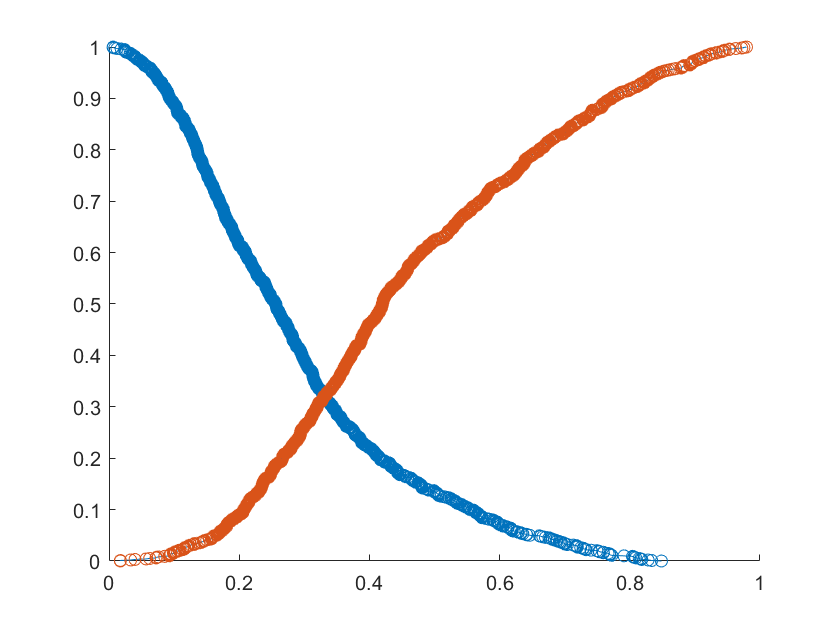

        cla
        [FT,XT]=ecdf(CRT_Total);
        [FI,XI]=ecdf(CRI_Total);
        B1=1-FT;
        A1=[XT,B1];
        A2=[XI,FI];
        line(XT,B1) %draw lines on the scatters.
        hold on
        line(XI,FI)
        scatter(XT,B1)
        scatter(XI,FI)
        hold off

        
         for i=2:size(A1,1)-1
            X1=A1(i,:);
            Y1=A1(i+1,:);
            for j=2:size(A2,1)-1
                X=[];
                Y=[];
                X2=A2(j,:);
                Y2=A2(j+1,:);
                [X,Y]=node(X1,Y1,X2,Y2);
                if X>=X1(1)&&X<=Y1(1)&&Y>=Y1(2)&&Y<=X1(2) && X>=X2(1)&&X<=Y2(1)&&Y>=X2(2)&&Y<=Y2(2)
                    X_NODE2=X;
                    Y_NODE=Y;
                    XY_NODE=[X,Y];
                    DD=[
                        X1(1),pdist2(X1,XY_NODE);
                        Y1(1),pdist2(Y1,XY_NODE);
                        X2(1),pdist2(X2,XY_NODE);
                        Y2(1),pdist2(Y2,XY_NODE);
                        ];
                    [R,C]=find(DD==min(DD(:,2)));
                    H %show H
                    n %show criteria number
                    Threshold_Proposed=DD(R)
                end
            end
        end

H = 9

n = 4

Threshold_Proposed = 0.3244

        
        CI_THRESHOLD=Threshold_Proposed;

## 4. Caculating Intransitive Consistency

        OR = [];
        for i3 = 1:size(IS,1) %cij has deleted all 1 vector.
            for j3 = 1:N/2
                F=0;
                for o3 = 1:N/2
                    x1=1/IS(i3,j3)-1/IS(i3,o3);
                    x2=IS(i3,j3+N/2)-IS(i3,o3+N/2);
                    x=x1*x2;
                    if x < 0
                        F=F+1;
                    elseif x==0 &&  (x1~=0 || x2 ~= 0)
                        F=F+1;
                    end
                end
            end
            OR=[OR;F];
        end

## 5.Plot

## 5.1 Ksdensity

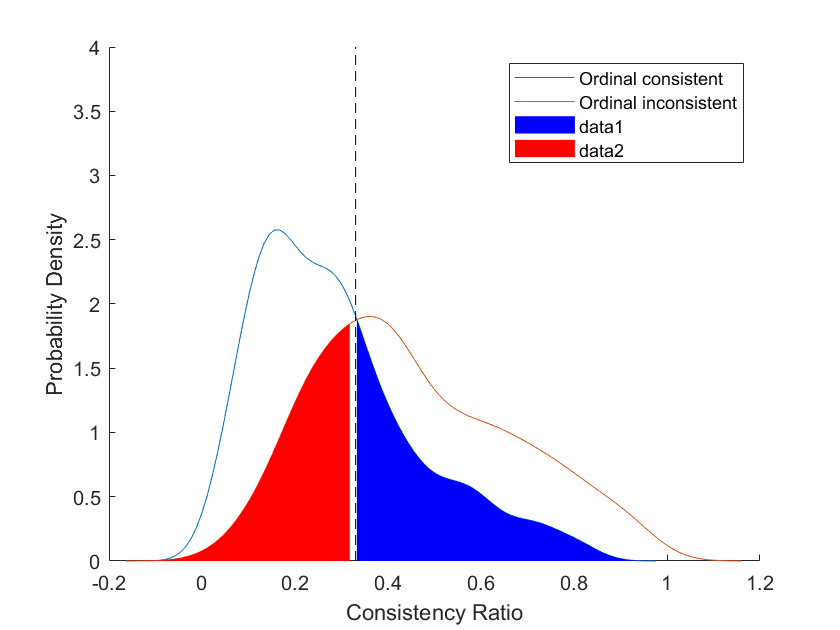

        CI_THRESHOLD1=max(CRT_Total);
        CI_THRESHOLD2=min(CRI_Total);
        ksdensity(CRT_Total);
        hold on;
        ksdensity(CRI_Total);
        plot([CI_THRESHOLD CI_THRESHOLD],[0 4], 'k--');
        xlabel('Consistency Ratio');
        ylabel('Probability Density');
        legend('Ordinal consistent','Ordinal inconsistent','Location','northeast');
        box off;
        
        
        %fill Transitive
        [y,x]=ksdensity(CRT_Total);
        idx=x>=CI_THRESHOLD&x<=1.2;
        xi=x(idx); yi=y(idx);
        fill([xi xi(end) xi(1)],[y(idx) 0 0],'b','facealpha',1,'edgecolor','none');
        
        %fill Intransitive
        [y,x]=ksdensity(CRI_Total);
        idx=x>=-0.2&x<=CI_THRESHOLD;
        xi=x(idx); yi=y(idx);
        fill([xi xi(end) xi(1)],[y(idx) 0 0],'r','facealpha',1,'edgecolor','none');
        hold off

## 5.2 Cumulated distribution plot

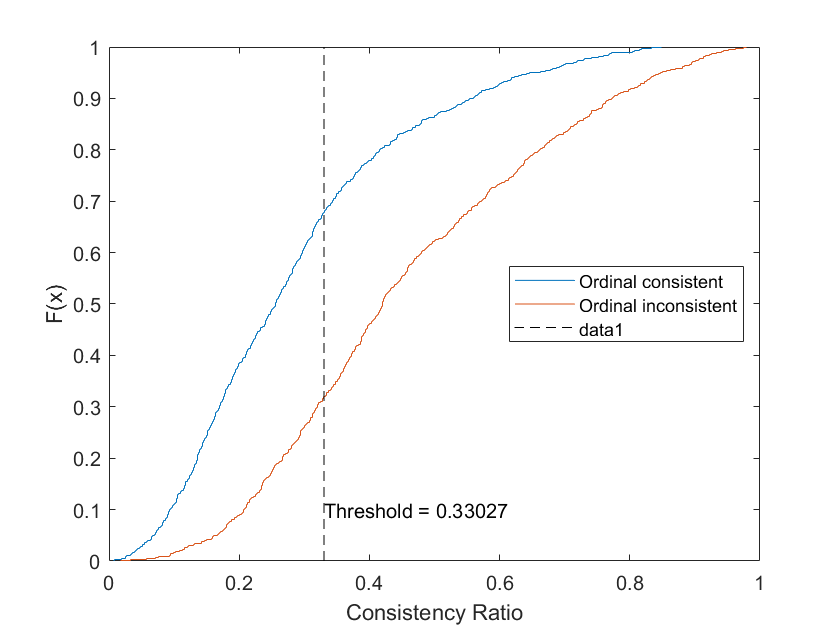

        %cumulated distribution plot
        ecdf(CRT_Total);
        hold on;
        ecdf(CRI_Total);
        xlabel('Consistency Ratio');
        ylabel('F(x)');
        legend('Ordinal consistent','Ordinal inconsistent','Location','East');

        %draw a line for CR threshold
        plot([CI_THRESHOLD CI_THRESHOLD],[0 1], 'k--');
        text(CI_THRESHOLD,0.1,['Threshold = ',num2str(CI_THRESHOLD)]);
        hold off

## 5.3 Histogram

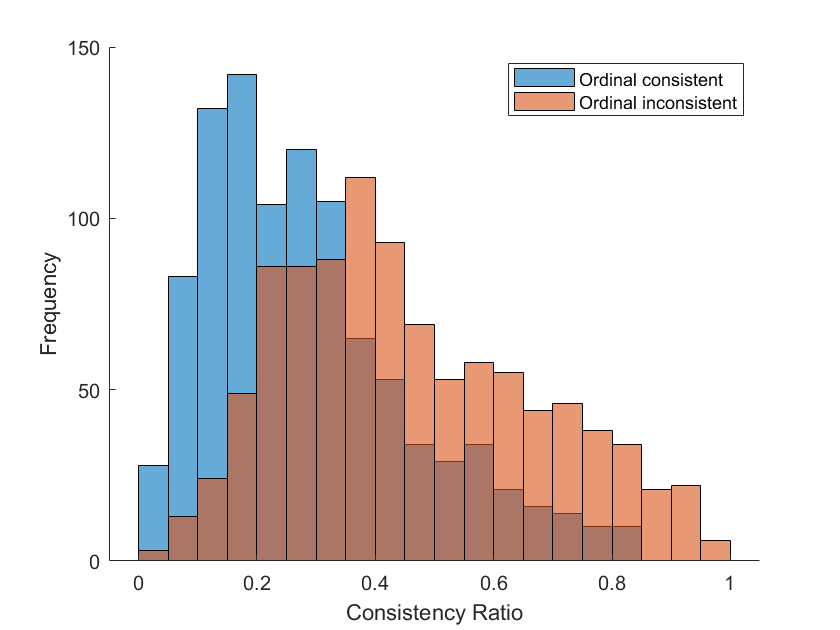

        histogram(CRT_Total);
        hold on
        histogram(CRI_Total);
        
        legend('Ordinal consistent','Ordinal inconsistent')
        xlabel('Consistency Ratio')
        ylabel('Frequency')
        box off

        hold off

        CI_THRESHOLD1=[n,H,CI_THRESHOLD]

CI_THRESHOLD1 =     4.0000    2.0000    0.3303


        CI_THRESHOLD_T=[CI_THRESHOLD_T;CI_THRESHOLD1];
        
    end
    CI_THRESHOLD_TT=[CI_THRESHOLD_TT CI_THRESHOLD]
end

CI_THRESHOLD_TT = 0.3303